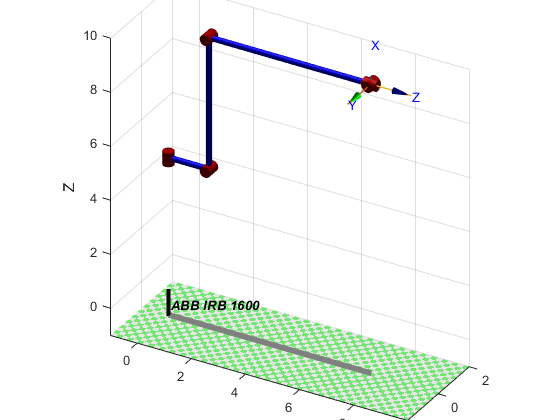

clear all
clc
clf
L1=4.87;
L2=1.5;
L3=4.88;
L4=6;
Q = [0 0 0 0 0 0];

L(1) = Link('revolute','alpha', 0,    'a',0,     'd',L1,   'offset', 0, ...
    'modified', 'qlim',[pi -pi]);
L(2) = Link('revolute','alpha', pi/2,  'a',L2,   'd',0,   'offset', pi/2, ...
    'modified', 'qlim',[110*pi/180 -63*pi/180]);
L(3) = Link('revolute','alpha', 0,    'a',L3,   'd',0,   'offset', 0, ...
    'modified', 'qlim',[55*pi/180 -235*pi/180]);
L(4) = Link('revolute','alpha', pi/2,    'a',0,   'd',L4,   'offset', 0, ...
    'modified', 'qlim',[200*pi/180 -200*pi/180]);
L(5) = Link('revolute','alpha', -pi/2,    'a',0,   'd',0,   'offset', 0, ...
    'modified', 'qlim',[115*pi/180 -115*pi/180]);
L(6) = Link('revolute','alpha', pi/2,    'a',0,   'd',0,   'offset', 0, ...
    'modified', 'qlim',[400*pi/180 -400*pi/180]);
bot = SerialLink(L, 'name', 'ABB IRB 1600');
bot.plot(Q,'workspace',[-1 10 -2 2 -1 10], 'xyz', 'view',[30 30])

syms q1 q2 q3 q4 q5 q6 L1 L2 L3 L4 real
Pi = sym(pi); %Definición de Pi como variable simbólica
%Parámetros DHm
Ls(1) = Link('revolute','alpha', 0,    'a',0,     'd',L1,   'offset', 0, ...
    'modified', 'qlim',[Pi -Pi]);
Ls(2) = Link('revolute','alpha', Pi/2,  'a',L2,   'd',0,   'offset', Pi/2, ...
    'modified', 'qlim',[110*Pi/180 -63*Pi/180]);
Ls(3) = Link('revolute','alpha', 0,    'a',L3,   'd',0,   'offset', 0, ...
    'modified', 'qlim',[55*Pi/180 -235*Pi/180]);
Ls(4) = Link('revolute','alpha', Pi/2,    'a',0,   'd',L4,   'offset', 0, ...
    'modified', 'qlim',[200*Pi/180 -200*Pi/180]);
Ls(5) = Link('revolute','alpha', -Pi/2,    'a',0,   'd',0,   'offset', 0, ...
    'modified', 'qlim',[115*Pi/180 -115*Pi/180]);
Ls(6) = Link('revolute','alpha', Pi/2,    'a',0,   'd',0,   'offset', 0, ...
    'modified', 'qlim',[400*Pi/180 -400*Pi/180]);
bots = SerialLink(Ls, 'name', 'ABB IRB 1600'); %Robot con parámetros simbólicos

Qs=[q1 q2 q3 q4 q5 q6];
%Matriz de transformación homogénea del robot
MTH = fkine(bots,Qs);
%MTHs de interés en el robot
T01 = Ls(1).A(q1);
T12 = Ls(2).A(q2);
T23 = Ls(3).A(q3);
T34 = Ls(4).A(q4);
T45 = Ls(5).A(q5);
T56 = Ls(6).A(q6);
T6t = bots.tool;
T02 = T01*T12;
T03 = T02*T23;
T04 = T03*T34;
T05 = T04*T45;
T06 = T05*T56;
T0t = T06*T6t;
%Vectores de traslación
P0t = T0t(1:3,4);
P1t = P0t-T01(1:3,4);
P2t = P0t-T02(1:3,4);
P3t = P0t-T03(1:3,4);
P4t = P0t-T04(1:3,4);
P5t = P0t-T05(1:3,4);
P6t = P0t-T06(1:3,4);
%Vectores unitarios de los ejes de rotación
Z01 = T01(1:3,3); %Eje articulación q1
Z02 = T02(1:3,3); %Eje articulación q2
Z03 = T03(1:3,3); %Eje articulación q3
Z04 = T04(1:3,3); %Eje articulación q4
Z05 = T05(1:3,3); %Eje articulación q5
Z06 = T06(1:3,3); %Eje articulación q6

%Jacobiano geométrico
Jo = [[skew(Z01)*P1t skew(Z02)*P2t skew(Z03)*P3t skew(Z04)*P5t skew(Z05)*P5t skew(Z06)*P6t;
       Z01           Z02           Z03           Z04           Z05           Z06 ]]

%Test
Variables = [q1 q2 q3 q4 q5 q6 L1 L2 L3 L4]; %Variables simbólicas a reemplazar
Q = [0 0 0 0 0 0]; %Valores articulares de entrada
q_test = [Q 4.87 1.5 4.88 6]; %Vector de valores para cada variable simbólica
J_geo = subs(Jo,Variables,q_test) %Sustitución de variables por valores numéricos en Jo

$$J\_geo = \left(\begin{array}{cccccc} 0 & -\frac{122}{25} & 0 & 0 & 0 & 0\\ \frac{15}{2} & 0 & 0 & 0 & 0 & 0\\ 0 & 6 & 6 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 1\\ 0 & -1 & -1 & 0 & -1 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


$$J_O =\left\lbrack \left\lbrack \begin{array}{c}
{}^0R_1\left({}^1{\hat{Z} }_1\times {}^1P_t\right)\\
{}^0R_1{}^1{\hat{Z} }_1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{}^0R_2\left({}^2{\hat{Z} }_2\times {}^2P_t\right)\\
{}^0R_2{}^2{\hat{Z} }_2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{}^0R_3\left({}^3{\hat{Z} }_3\times {}^3P_t\right)\\
{}^0R_3{}^3{\hat{Z} }_3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{}^0R_4\left({}^4{\hat{Z} }_4\times {}^4P_t\right)\\
{}^0R_4{}^4{\hat{Z} }_4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{}^0R_5\left({}^5{\hat{Z} }_5\times {}^5P_t\right)\\
{}^0R_5{}^5{\hat{Z} }_5
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{}^0R_6\left({}^6{\hat{Z} }_6\times {}^6P_t\right)\\
{}^0R_6{}^6{\hat{Z} }_6
\end{array}\right\rbrack \right\rbrack$$


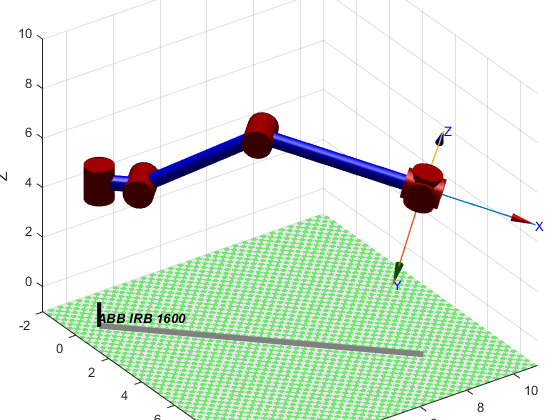

clf
Q2 = [pi/4 -pi/3 pi/4 pi/2 -pi/2 0]; 
bot.plot(Q2,'workspace',[-2 11 -1 11 -1 10], 'xyz', 'view',[55 30])


J_geo2 = bot.jacob0(Q2) %Obtención del Jacobiano geométrico

J_geo2 =    -8.1410   -0.6237    1.0981         0         0         0
    8.1410   -0.6237    1.0981         0         0         0
    0.0000   10.0131    5.7956         0         0         0
   -0.0000    0.7071    0.7071    0.6830   -0.1830   -0.7071
   -0.0000   -0.7071   -0.7071    0.6830   -0.1830    0.7071
    1.0000    0.0000    0.0000   -0.2588   -0.9659   -0.0000


v = [100 200 50]; %Vector de velocidades lineales
w = [5 10 -5]; %Vector de velocidades angulares
vw = [v w]'; %Vector generalizado de velocidades 
q_dot = inv(J_geo2)*vw %Obtención de las velocidades articulares

q_dot =     6.1418
  -55.7447
  104.9385
   13.1289
    8.0169
   52.7294



$${J_O }^{-1} \cdot \left\lbrack \begin{array}{c}
v\\
\omega 
\end{array}\right\rbrack =\overset{\cdot }{q}$$
